# N9_Matched Filter Design and Utilization for Signal Detection

Sam Kramer

January 18th, 2024

Thesis Research

This notebook will be used for the creation of matched filters and implementing them to see their feasibility for weak signal detection for the purpose of thesis research. The matched filter will be used to compare against the KCC and XCC algorithms to provide an insight into the usefulness of the algorithms.

## Setup Signals and Noise

Creating the signals and the noisy signals for the use in the examples.

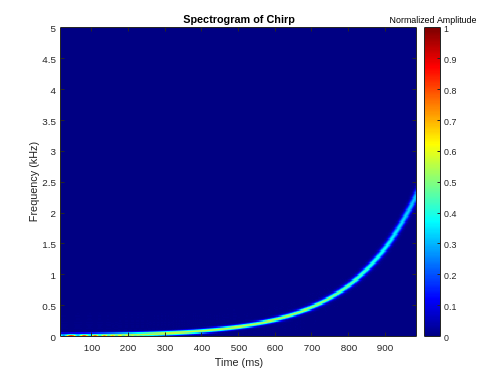

% --Generate Signals
    clear; clc; format compact; close all;

% --Generate basic signal (no noise)

    % --Signal Parameters
        T = 1;              % Signal Period T (s)
        fs = 10000;         % Sample Rate (Hz)
        t = 0:1/fs:T;
        f = 10*2*pi;        % Frequency (Hz)

    % --Create signal
        amplitude = 0.5;
        envelope = amplitude.* sin(pi*t);
        ref_signal = envelope .* sin(f*t);

% --Creating Chirp
    chirp = create_chirp("logarithmic", 1, 1, 10, 2500, fs+1, "true");
    title("Spectrogram of Chirp")

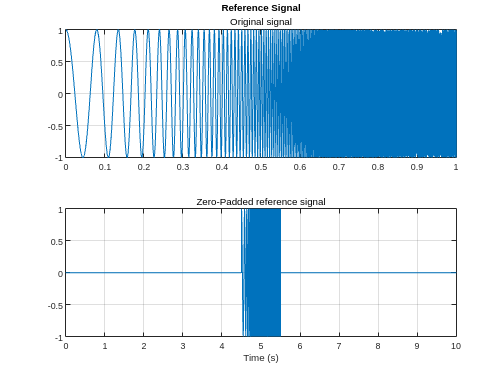

% --Zero padding signal
    time = 0:1/fs:10;
    zero_pad = zeros(1,(length(time) - length(t))/2);
    ref_signal_long = [zero_pad, ref_signal, zero_pad];
    ref_chirp_long = [zero_pad, chirp', zero_pad];
    
% --Plotting
    figure()
    subplot(2,1,1)
    plot(t, chirp)
        hold on
        grid on
        title("Reference Signal")
        subtitle("Original signal")

    subplot(2,1,2)
    plot(time, ref_chirp_long)
        hold on
        grid on
        subtitle("Zero-Padded reference signal")
    xlabel("Time (s)")

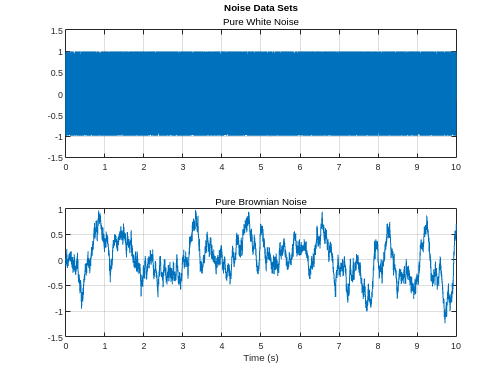

% --Noise Generation

    % --Pure white noise data
        white_data = randi(100, 1, length(ref_signal_long))./50;
        white_data = white_data - mean(white_data);

    % --Developing Brownian Noise analysis
        cn = dsp.ColoredNoise('brown', length(ref_signal_long));
        brownian_data = cn();
        brownian_data = brownian_data ./ 100;
        brownian_data = [brownian_data - mean(brownian_data)]';

% --Plotting Noise 
    figure()
    subplot(2,1,1)
    plot(time, white_data)
        hold on
        grid on
        ylim([- 1.5 1.5])
        subtitle('Pure White Noise')
        title('Noise Data Sets')

    subplot(2,1,2)
    plot(time, brownian_data)
        grid on
        xlabel("Time (s)")
        subtitle('Pure Brownian Noise')

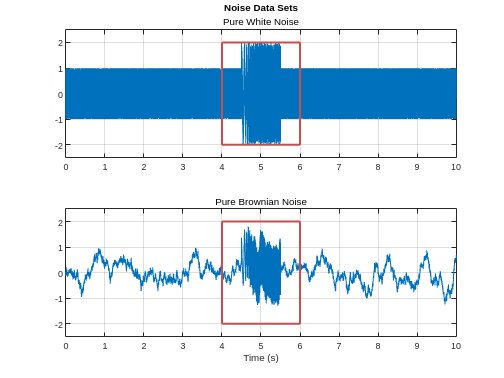

% --Combining the data sets
    white_signal = white_data + ref_chirp_long;
    brown_signal = brownian_data + ref_chirp_long;

% --Creating the squares
    x = [4, 6];
    x2 = [6, 6];
    x3 = [4, 4];
    y = [-2, -2];
    y2 = [2, 2];
    y3 = [2, -2];

% --Plotting signals
    figure()
    subplot(2,1,1)
    plot(time, white_signal)
        hold on
        grid on
        ylim([- 2.5 2.5])
        subtitle('Pure White Noise')
        title('Noise Data Sets')
        plot(x, y, 'LineWidth', 2, 'Color', [0.8 0.3 0.3])
        plot(x, y2, 'LineWidth', 2, 'Color', [0.8 0.3 0.3])
        plot(x2, y3, 'LineWidth', 2, 'Color', [0.8 0.3 0.3])
        plot(x3, y3, 'LineWidth', 2, 'Color', [0.8 0.3 0.3])

    subplot(2,1,2)
    plot(time, brown_signal)
        grid on
        hold on
        ylim([-2.5 2.5])
        xlabel("Time (s)")
        plot(x, y, 'LineWidth', 2, 'Color', [0.8 0.3 0.3])
        plot(x, y2, 'LineWidth', 2, 'Color', [0.8 0.3 0.3])
        plot(x2, y3, 'LineWidth', 2, 'Color', [0.8 0.3 0.3])
        plot(x3, y3, 'LineWidth', 2, 'Color', [0.8 0.3 0.3])
        subtitle('Pure Brownian Noise')

## Creating the Matched Filter

Creating the matched filter and then using it in the signal detection

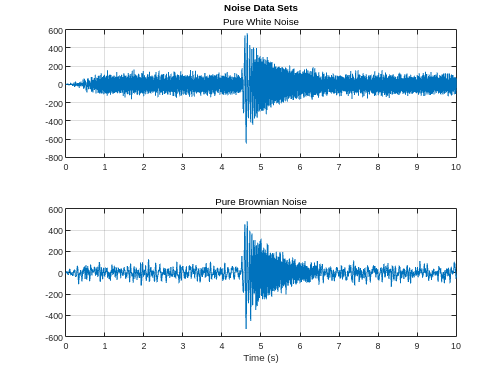

% --Create matched filters
    ref_b = conj(fliplr(chirp));
    ref_matched = filter(ref_b, 1,ref_chirp_long);

    white_b = conj(white_signal(end:-1:1));
    white_filtered = filter(ref_b, 1, white_signal);

    brown_b = conj(brown_signal(end:-1:1));
    brown_filtered = filter(ref_b, 1, brown_signal);

% --Outputs
    figure()
    subplot(2,1,1)
    plot(time, white_filtered)
        hold on
        grid on
        %ylim([- 2.5 2.5])
        subtitle('Pure White Noise')
        title('Noise Data Sets')
        
    subplot(2,1,2)
    plot(time, brown_filtered)
        grid on
        hold on
        %ylim([-2.5 2.5])
        xlabel("Time (s)")
        subtitle('Pure Brownian Noise')